# Asesoria Metodos numericos

### Asesoria 24/05/2022

clear
syms f(x)
format short

f(x) = exp(x / .4);

d4f(x) = diff(f, 4);
d5f(x) = diff(d4f);
c = vpasolve(d5f(x) == 0)

 
c =
 
Empty sym: 0-by-1
 


d4f(0), eval(d4f(2))

$$ans = \frac{625}{16}$$

ans = 5.7974e+03

C = eval(abs( d4f(2) / factorial(4) ))

C = 241.5579

factorial(4)

ans = 24

(1/24) * 5.7974e+03 % Decimales

ans = 241.5583

### Asesoria 27/05/2022

clear
syms f(t, y) a b c d P(x)

f(t, y) = (y - 1)*exp(-y)

$$f(t, y) = {\mathrm{e}}^{-y}\,\left(y-1\right)$$

df = diff(f, t) + f * diff(f, y);
matlabFunction(df)

ans = function_handle with value:
    @(t,y)exp(-y).*(exp(-y)-exp(-y).*(y-1.0)).*(y-1.0)


 P(x) = poly2sym([a b c d], x)

$$P(x) = a\,x^{3}+b\,x^{2}+c\,x+d$$

 P(x) = P(x - 1)

$$P(x) = d+c\,\left(x-1\right)+a\,{\left(x-1\right)}^{3}+b\,{\left(x-1\right)}^{2}$$

clear
syms h l w T_i T_j T_m T_n T_f real

C1 =  h * l  / 6 * [2 1 0 0; 1 2 0 0; zeros([2, 4])];
D1 = h * w / 6 * [ zeros(1, 4); 0 2 1 0; 0 1 2 0; zeros(1, 4)];
E1 = h * l / 6 * [zeros(2, 4); 0 0 2 1; 0 0 1 2];
F1 = h * w / 6 * [2 0 0 1; zeros(2, 4); 1 0 0 2];
C2 = l/2 * [1 1 0 0]';
D2 = w/2 * [0 1 1 0]';
E2 = l/2 * [0 0 1 1]';
F2 = w/2 * [1 0 0 1]';

T = [T_i T_j T_m T_n]';

(C1 + D1 + E1 + F1)*T + h * T_f / 2 * (C2 + D2 + E2 + F2)

$$ans = \begin{array}{l} \left(\begin{array}{c} T_{i}\,\sigma_{2}+\sigma_{1}+\frac{T_{j}\,h\,l}{6}+\frac{T_{n}\,h\,w}{6}\\ T_{j}\,\sigma_{2}+\sigma_{1}+\frac{T_{i}\,h\,l}{6}+\frac{T_{m}\,h\,w}{6}\\ T_{m}\,\sigma_{2}+\sigma_{1}+\frac{T_{n}\,h\,l}{6}+\frac{T_{j}\,h\,w}{6}\\ T_{n}\,\sigma_{2}+\sigma_{1}+\frac{T_{m}\,h\,l}{6}+\frac{T_{i}\,h\,w}{6} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{T_{f}\,h\,\left(\frac{l}{2}+\frac{w}{2}\right)}{2}\\ \sigma_{2}=\frac{h\,l}{3}+\frac{h\,w}{3} \end{array}$$

eval(simplify(ans))

$$ans = \left(\begin{array}{c} \frac{h\,\left(3\,T_{f}\,l+4\,T_{i}\,l+2\,T_{j}\,l+3\,T_{f}\,w+4\,T_{i}\,w+2\,T_{n}\,w\right)}{12}\\ \frac{h\,\left(3\,T_{f}\,l+2\,T_{i}\,l+4\,T_{j}\,l+3\,T_{f}\,w+4\,T_{j}\,w+2\,T_{m}\,w\right)}{12}\\ \frac{h\,\left(3\,T_{f}\,l+4\,T_{m}\,l+2\,T_{n}\,l+3\,T_{f}\,w+2\,T_{j}\,w+4\,T_{m}\,w\right)}{12}\\ \frac{h\,\left(3\,T_{f}\,l+2\,T_{m}\,l+4\,T_{n}\,l+3\,T_{f}\,w+2\,T_{i}\,w+4\,T_{n}\,w\right)}{12} \end{array}\right)$$

collect(eval(simplify(ans)), [l, w])

$$ans = \left(\begin{array}{c} \frac{h\,\left(3\,T_{f}+4\,T_{i}+2\,T_{j}\right)}{12}\,l+\frac{h\,\left(3\,T_{f}+4\,T_{i}+2\,T_{n}\right)}{12}\,w\\ \frac{h\,\left(3\,T_{f}+2\,T_{i}+4\,T_{j}\right)}{12}\,l+\frac{h\,\left(3\,T_{f}+4\,T_{j}+2\,T_{m}\right)}{12}\,w\\ \frac{h\,\left(3\,T_{f}+4\,T_{m}+2\,T_{n}\right)}{12}\,l+\frac{h\,\left(3\,T_{f}+2\,T_{j}+4\,T_{m}\right)}{12}\,w\\ \frac{h\,\left(3\,T_{f}+2\,T_{m}+4\,T_{n}\right)}{12}\,l+\frac{h\,\left(3\,T_{f}+2\,T_{i}+4\,T_{n}\right)}{12}\,w \end{array}\right)$$

clear
syms X [1 3]
syms a A
assume(X, 'positive')

x = [X1 X2 X3];
R = norm(X);
r = (R^3 + a^3 - A^3)^(1/3);
phi = [r*X1/R r*X2/R r*X3/R];
F = simplify(jacobian(phi, X));
F = collect(F, X)

$$F = \begin{array}{l} \left(\begin{array}{ccc} \left(-\sigma_{1}\right)\,{X_{2}}^{2}+\left(-\sigma_{1}\right)\,{X_{3}}^{2}+\sigma_{2} & \sigma_{1}\,X_{1}\,X_{2} & \sigma_{1}\,X_{1}\,X_{3}\\ \sigma_{1}\,X_{1}\,X_{2} & \left(-\sigma_{1}\right)\,{X_{1}}^{2}+\left(-\sigma_{1}\right)\,{X_{3}}^{2}+\sigma_{2} & \sigma_{1}\,X_{2}\,X_{3}\\ \sigma_{1}\,X_{1}\,X_{3} & \sigma_{1}\,X_{2}\,X_{3} & \left(-\sigma_{1}\right)\,{X_{1}}^{2}+\left(-\sigma_{1}\right)\,{X_{2}}^{2}+\sigma_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{A^{3}-a^{3}}{{\left(a^{3}-A^{3}+{\left({X_{1}}^{2}+{X_{2}}^{2}+{X_{3}}^{2}\right)}^{3/2}\right)}^{2/3}\,{\left({X_{1}}^{2}+{X_{2}}^{2}+{X_{3}}^{2}\right)}^{3/2}}\\ \sigma_{2}=\frac{{X_{1}}^{2}+{X_{2}}^{2}+{X_{3}}^{2}}{{\left(a^{3}-A^{3}+{\left({X_{1}}^{2}+{X_{2}}^{2}+{X_{3}}^{2}\right)}^{3/2}\right)}^{2/3}} \end{array}$$

clear
f=@(x) sin(pi*x/4);
g1=@(t) 0*t;
g2=@(t) exp(-pi^2*t);
U = forwdif2 (f, g1, g2, 2, 0.6, 4, 5, 4)

U =          0    0.3827    0.7071    0.9239    1.0000
         0   -0.3630   -0.6708   -0.8765    0.1389
         0    0.3444    0.6364   14.7527    0.0193
         0   -0.3267  177.5878 -354.5238    0.0027


xtick = 0:2/4:2;
ytick = 0:.6/3:.6;
[x, y] = meshgrid(xtick, ytick)

x =          0    0.5000    1.0000    1.5000    2.0000
         0    0.5000    1.0000    1.5000    2.0000
         0    0.5000    1.0000    1.5000    2.0000
         0    0.5000    1.0000    1.5000    2.0000


y =          0         0         0         0         0
    0.2000    0.2000    0.2000    0.2000    0.2000
    0.4000    0.4000    0.4000    0.4000    0.4000
    0.6000    0.6000    0.6000    0.6000    0.6000


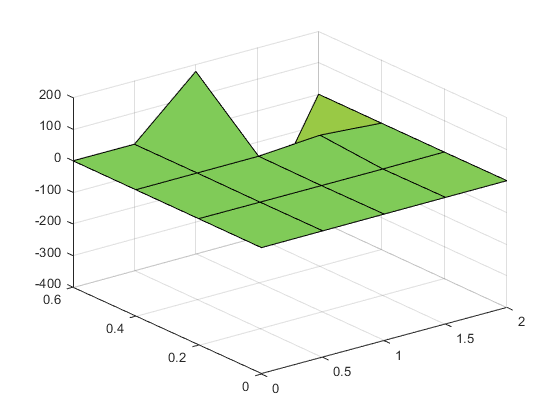

surf(x, y, U)

% Referencia de código
clear
a = 0; b = 2; ya = .5; M = 10;
syms f(t, y)
f(t, y) = y + cos(t) + 1;
df(t, y) = diff(f, t) + f(t, y) * diff(f, y);
d2f(t, y) = diff(df, t) + df(t, y) * diff(df, y);

df = [f, df, d2f, 0];

f = matlabFunction(f);
df = matlabFunction(df);

T3 = taylor(df, a, b, ya, M);

fext = @(t) 2*exp(t) + .5*(sin(t) - cos(t)) - 1;

T3(T3 == 1.6,:) % Valor evaluado en t = 1.6, y(t = 1.6)

ans =     1.6000    9.4059


b % Valor de b

b = 2

errb = abs((fext(b) - T3(end, 2)) / fext(b)) % Error en b

errb = 0.0018

errt = abs((fext(1.6) - T3(T3 == 1.6, 2)) / fext(1.6)) % Error en 1.6

errt = 0.0015